# photometric attitude estimation using UKF on Lie group (quaternion) not yet

UKFでlight curve attitude estimation

## state variables


$${\bf x}=[{\bf q}^T, {\bf \omega}^T]^T$$


`q`: quaternion where q(4) is the scalar part 

`w`: angular rate, rad/s

## note

NA

## references 

NA

## revisions

20240831  y.yoshimura, y.yoshimula@gmail.com

See also orbitConst, mainATOM.

clc
clear
cls

## constants

earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

## simulation conditions

% true value calculated by mainAttiOrbit.mlx
fName = "flatPlate";
load(strcat(fName,'.mat'));

% random number generator
rng(2022,'twister');

## observations and noise

tn_ = length(t_);

sigMapp = 0.1;
mAppNoise = mApp + sigMapp .* randn(tn_, 1);

% observations
dTmp = vecnorm(obsRel, 2, 2); % m, distance between sat and observer
mAppInv = magInv(mAppNoise(:,1), dTmp); % true obs. (relative magnitude inverse)

## UKF paras.

n_ = 4; % # of state variable := quaternion
nP_ = 3;

### UKF parameters

ukfPara.alpha = 1e-4;
ukfPara.beta = 2;
ukfPara.kappa = 0;
ukfPara.lambda = 0.6;
ukfPara = setUKFpara(n_, ukfPara);

checking normalization:
weights for mean
     1

weights for covariance
    4.0000




% ↓ paperの
% nz = 3;
% ukfPara.lambda = 1 * nz * (ukfPara.alpha^2 - 1);
% ukfPara.w0c = ukfPara.lambda / (nz+ukfPara.lambda) + nz - ukfPara.alpha^2;
% ukfPara.wic = 1 / 2 / (nz + ukfPara.lambda);
% ukfPara.w0m = ukfPara.lambda / (nz + ukfPara.lambda);
% ukfPara.wim = 1 / 2 / (nz + ukfPara.lambda);
ukfPara

ukfPara = フィールドをもつ struct :
     alpha: 1.0000e-04
      beta: 2
     kappa: 0
    lambda: 0.6000
       w0m: 0.1304
       wim: 0.1087
       w0c: 3.1304
       wic: 0.1087



% estimated observation noise (standard deviation)
Rest = (3 * sigMapp).^2;
Qest = 0 * deg2rad(1e-2)^2 .* eye(nP_); % process noise


### pre-allocation

xEst = zeros(tn_, n_); % [euler angles, angular rates]
p = zeros(tn_, nP_); % diagonal components of covariance matrix (Pcov)


## initial estiamte and covariance

xEst(1,:) = q(1,:);  % true initial
tmp = zyx2q(4, deg2rad(-20), ...
    deg2rad(50), ...
    deg2rad(30)); % initial estimate error of quaternion
xEst(1,:) = qMult(4, 1, tmp, q(1,:));


#### initial covariance for 3$\sigma
$bound 

p(1,:) = deg2rad(150)^2 .* ones(1,3);
% p(1,:) = 2.618^2 .* ones(1,3);
Pcov = diag(p(1,:));

global nWindow ind adapNoise Qest Rest

ind = 1;
nWindow = 6;

## UKF

for i = 1:tn_-1
    dt_ = t_(i+1) - t_(i);

    if i > nWindow
        adapNoise = 1;
    else
        adapNoise = 0;
    end

    [xEst(i+1,:), Pcov] = lcUKFonLieGroup(jdHistory(i+1), dt_, xEst(i,:), Pcov, mAppNoise(i+1), ...
        ukfPara,  w(i,:), r(i+1,:), obsECI(i+1,:), sat, const, earthVSOP);

end

no observation update
no observation update
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no observation update due to predicted obs. value
no obs

## data handling

qe = qErr(4, q, xEst);
zyxE = q2zyx(4, qe);
phiE = zyxE(:,1);
thetaE = zyxE(:,2);
psiE = zyxE(:,3);


## show figures

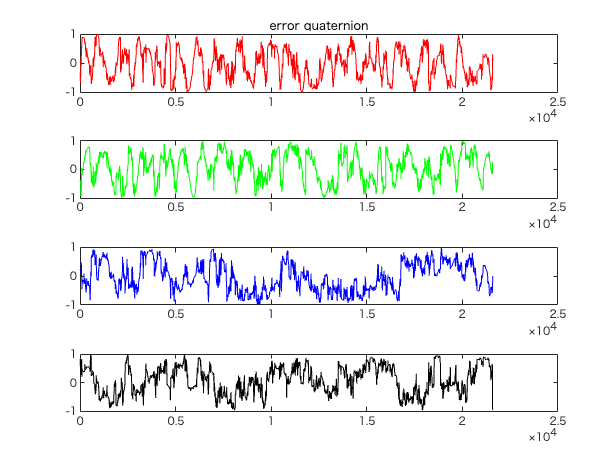

figure
tiledlayout(4,1),nexttile
plot(t_, qe(:,1), 'r')
title('error quaternion')
nexttile
plot(t_, qe(:,2), 'g')
nexttile
plot(t_, qe(:,3), 'b')
nexttile
plot(t_, qe(:,4), 'k')

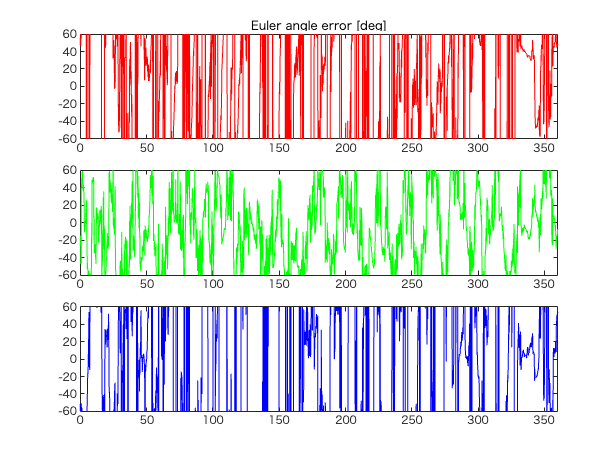


figure
tiledlayout(3,1),nexttile
plot(t_/60, rad2deg(phiE), 'r')
title('Euler angle error [deg]')
xlim([0 60*6]),ylim([-60 60])
nexttile
plot(t_/60, rad2deg(thetaE), 'g')
xlim([0 60*6]),ylim([-60 60])
nexttile
plot(t_/60, rad2deg(psiE), 'b')
xlim([0 60*6]),ylim([-60 60])